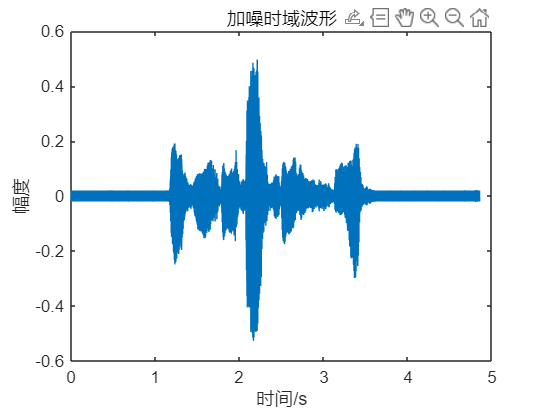

% 清空工作区和命令窗口
clc;clear;

% 读取音频文件并添加噪声
[y0,Fs] = audioread('dspx1.wav');    % 读取音频文件，y0为音频数据，Fs为采样频率
t = (0:length(y0)-1) / Fs;          % 生成时间序列
f = 4000;                           % 设置噪声频率为4000Hz
A = 0.02;                           % 设置噪声幅度
Nt = (A*cos(2*pi*f*t))';           % 生成余弦噪声信号
y = y0 + Nt;                        % 将噪声信号添加到原始音频

%% 绘制加噪后的信号分析图
% 绘制时域波形
figure;
plot(t, y);
title('加噪时域波形');
xlabel('时间/s');
ylabel('幅度');

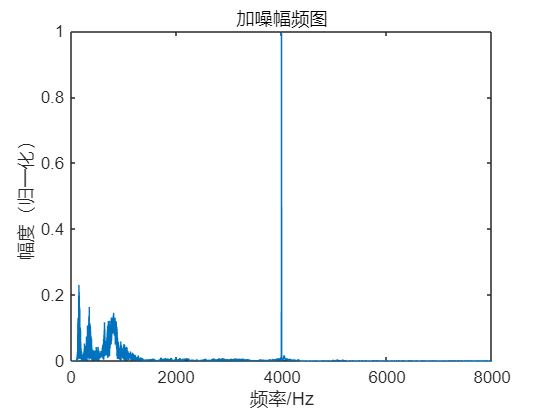


% 绘制幅频图
figure;
n = length(y);                      % 获取信号长度
Y0 = fft(y);                        % 对信号进行傅里叶变换
f = (0:n-1)*Fs/n;                  % 计算频率轴
Y = abs(Y0)/abs(max(Y0));          % 计算幅度谱并归一化
plot(f, Y);
title('加噪幅频图');
xlabel('频率/Hz');
ylabel('幅度（归一化）');
xlim([0,8000]);                    % 限制频率显示范围


%% 巴特沃兹低通滤波器设计与应用
% 设置滤波器参数
wp = 2000*2*pi/Fs;                  % 通带截止频率（2000Hz）
ws = 3800*2*pi/Fs;                  % 阻带截止频率（3800Hz）
rp = 3;                             % 通带最大衰减（dB）
rs = 40;                            % 阻带最小衰减（dB）

% 频率预畸变
wp = 2*Fs*tan(wp/2);               % 将数字频率转换为模拟频率
ws = 2*Fs*tan(ws/2);

% 设计巴特沃兹滤波器
[N, wn] = buttord(wp,ws, rp, rs, 's');  % 计算滤波器阶数N和截止频率wn
[A,B] = butter(N, wn, 's');             % 设计巴特沃兹滤波器
[num1, den1] = bilinear(A, B,Fs);       % 双线性变换，将模拟滤波器转换为数字滤波器

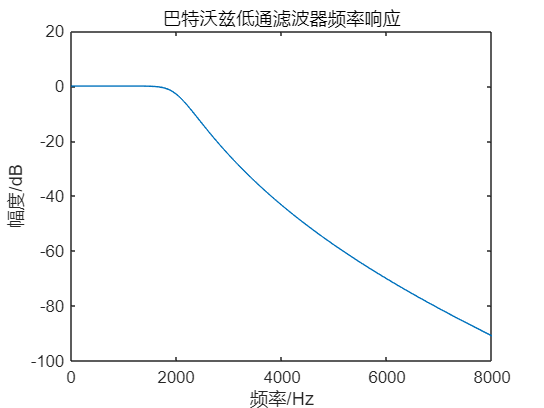


% 绘制滤波器频率响应
[h1,w] = freqz(num1, den1);
w = w/2/pi*Fs;
figure;
plot(w,20*log10(abs(h1)));
xlim([0,8000]);
xlabel('频率/Hz'); 
ylabel('幅度/dB');
title('巴特沃兹低通滤波器频率响应');

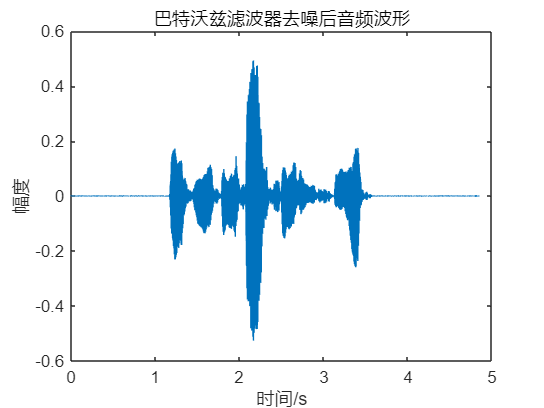


% 应用巴特沃兹滤波器并绘制结果
y1 = filter(num1,den1,y);          % 对含噪声信号进行滤波

% 绘制滤波后的时域波形
figure;
plot(t,y1);
title('巴特沃兹滤波器去噪后音频波形');
xlabel('时间/s');
ylabel('幅度');

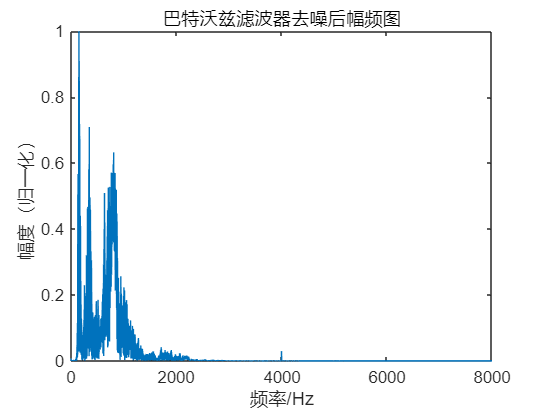


% 绘制滤波后的频谱
figure;
Y1 = fft(y1); 
M1 = max(Y1);
f = (0:n-1)*Fs/n;
Y1 = abs(Y1)/abs(M1); 
plot(f, Y1);
title('巴特沃兹滤波器去噪后幅频图');
xlabel('频率/Hz');
ylabel('幅度（归一化）');
xlim([0,8000]);


%% 椭圆低通滤波器设计与应用
% 设计椭圆滤波器（参数与巴特沃兹滤波器相同）
[N, wn] = ellipord(wp,ws, rp, rs, 's');    % 计算椭圆滤波器阶数和截止频率
[A,B] = ellip(N,rp,rs,wp,'s');             % 设计椭圆滤波器
[num2, den2] = bilinear(A, B,Fs);          % 转换为数字滤波器

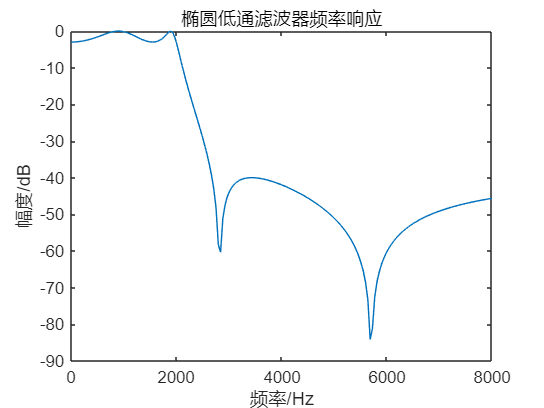


% 绘制滤波器频率响应
[h2,w] = freqz(num2, den2);
w = w/2/pi*Fs;
figure;
plot(w,20*log10(abs(h2)));
xlim([0,8000]);
xlabel('频率/Hz'); 
ylabel('幅度/dB');
title('椭圆低通滤波器频率响应');

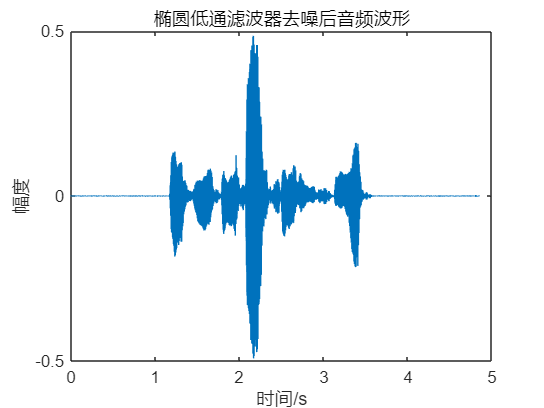


% 应用椭圆滤波器并绘制结果
y2 = filter(num2,den2,y);          % 对含噪声信号进行滤波

% 绘制滤波后的时域波形
figure;
plot(t,y2);
title('椭圆低通滤波器去噪后音频波形');
xlabel('时间/s');
ylabel('幅度');

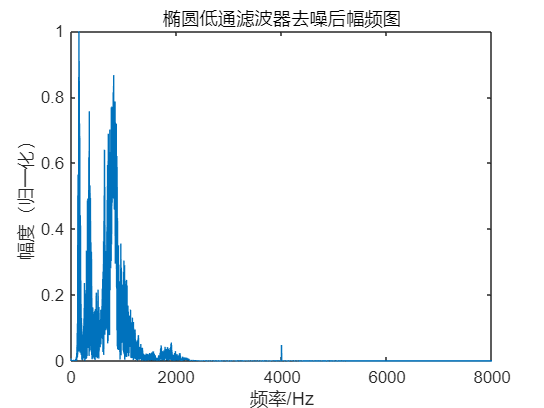


% 绘制滤波后的频谱
figure;
Y2 = fft(y2); 
M1 = max(Y2);
f = (0:n-1)*Fs/n;
Y2 = abs(Y2)/abs(M1); 
plot(f, Y2);
title('椭圆低通滤波器去噪后幅频图');
xlabel('频率/Hz');
ylabel('幅度（归一化）');
xlim([0,8000]);